Параметры системы

A = [0 1;
     9 0];
B_1 = [1;
       3];
B_2 = [1;
       0];
D_1 = [-5];

C_1 = [2 -3];

Первый выход

C_2 = [0 6;
    4 2;
    8 0];
D_2 = [1; 2; 3];

Наблюдатель системы

[P, L] = H2_observer(A, B_1, C_1, D_1)

P =     3.2197    9.6591
    9.6591   28.9772


L =     0.9015
    2.7045


Матрица регулятора

[Q_1, K_1] = H2_controller(A, B_2, C_2, D_2)

Q_1 =   107.5958   41.4955
   41.4955   22.5904


K_1 =    -7.6854   -2.9640


Передаточная функция системы

sys_1 = ss([A, B_2*K_1; -L*C_1, A+B_2*K_1+L*C_1],[B_1; -L*D_1], [C_2, D_2*K_1], 0);
[num, den] = sys2TfParam(sys_1);
disp(num)

    {[   0 -56.7232 -22.8541 -1.7025e+03 -6.4334e+03]}
    {[   0 -139.4464 -786.4972 -1.2995e+03 -585.1681]}
    {[0 -216.1697 -1.4482e+03 -1.4790e+03 2.7599e+03]}



disp(den)

    {[1 13.9960 76.1069 187.8735 175.5504]}
    {[1 13.9960 76.1069 187.8735 175.5504]}
    {[1 13.9960 76.1069 187.8735 175.5504]}



Вычисление норм системы

G = [tf(num(1), den(1));
    tf(num(2), den(2));
    tf(num(3), den(3))];
disp(norm(G, 2))

   76.9280



disp(hinfnorm(G))

   40.0159



Вторая пара для вых воздействия

C_21 = [1 0;
    0 1;
    0 0];
D_21 = [0; 0; 1];

Матрица регулятора 

[Q_2, K_2] = H2_controller(A, B_2, C_21, D_21)

Q_2 =     6.6675    2.4142
    2.4142    1.0477


K_2 =    -6.6675   -2.4142


Передаточная функция системы

sys_2 = ss([A, B_2*K_2; -L*C_1, A+B_2*K_2+L*C_1],[B_1; -L*D_1], [C_21, D_21*K_2], 0);
[num1, den1] = sys2TfParam(sys_2);
disp(num1)

    {[  0 1.0000 -46.7228 -163.2141 -42.1369]}
    {[0 3.0000 47.9343 -226.2984 -1.0293e+03]}
    {[ 0 -62.7009 -275.8841 37.6206 902.8936]}



disp(den1)

    {[1 12.9781 64.7357 146.5410 126.4108]}
    {[1 12.9781 64.7357 146.5410 126.4108]}
    {[1 12.9781 64.7357 146.5410 126.4108]}



Вычисление норм системы

G1 = [tf(num1(1), den1(1));
    tf(num1(2), den1(2));
    tf(num1(3), den1(3))];
disp(norm(G1, 2))

   19.7514



disp(hinfnorm(G1))

   11.2118



Построение графиков

График сингулярных чисел

% sigma(sys_1);
% hold on;
% grid on;
% sigma(sys_2);
% legend('σ1', 'σ2');
% hold off;

Покомпонентные АЧХ системы

% bodemag(sys_1);
% hold on;
% grid on;
% bodemag(sys_2);
% legend('System 1', 'System 2');
% hold off;

Построение графиков с возмущающим воздействием

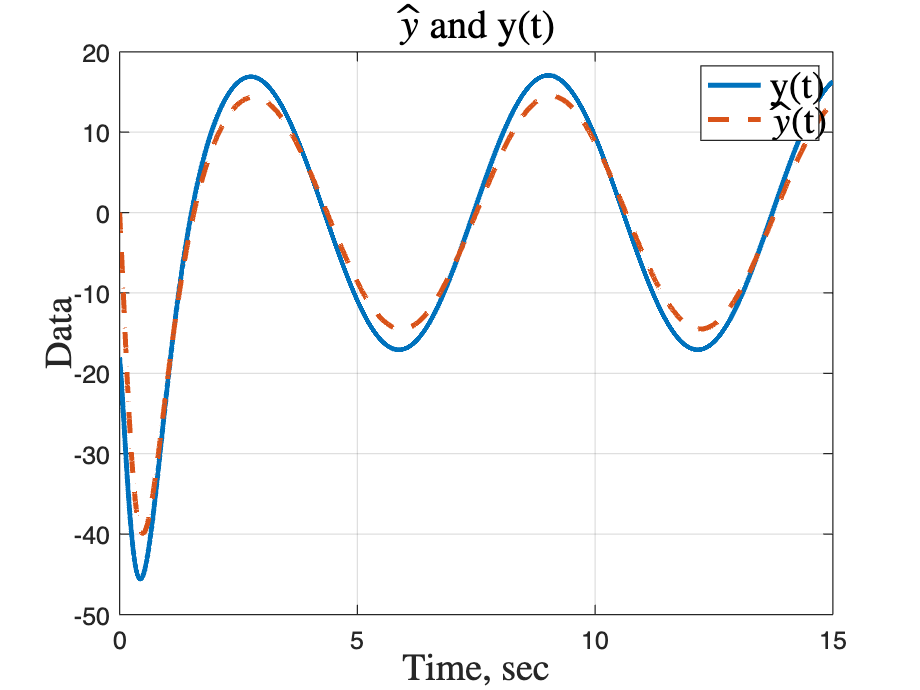

x_0 = [3; 8];
% 
% plot(out.z.Time, out.z.Data(:, 1), LineWidth=2.0);
% hold on;
% plot(out.z1.Time, out.z1.Data(:, 1), LineWidth=2.0);
% title('$z_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
% xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% 
% hold off;
% plot(out.z.Time, out.z.Data(:, 2), LineWidth=2.0);
% hold on;
% plot(out.z1.Time, out.z1.Data(:, 2), LineWidth=2.0);
% title('$z_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
% xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);
% grid on;
% 
% hold off;
% plot(out.z.Time, out.z.Data(:, 3), LineWidth=2.0);
% hold on;
% plot(out.z1.Time, out.z1.Data(:, 3), LineWidth=2.0);
% grid on;
% title('$z_{u}(t)$','Interpreter', 'latex', 'FontSize', 16);
% xlabel('time', 'Interpreter', 'latex', 'FontSize', 15);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% legend('System 1', 'System 2', 'Interpreter', 'latex', 'FontSize', 15);

z2 = reshape(out.z1.Data,[5005,3]);
hold off;
plot(out.z.Time, out.z.Data(:, 1), LineWidth=2.0);
hold on;
plot(out.z1.Time, z2(:, 1), LineWidth=2.0, LineStyle="--");
grid on;
title('$\hat{z_{1}}$ and z(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("z(t)","$\hat{z_{1}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);

hold off;

plot(out.z.Time, out.z.Data(:, 2), LineWidth=2.0);
hold on;
plot(out.z1.Time, z2(:, 2), LineWidth=2.0, LineStyle="--");
grid on;
title('$\hat{z_{2}}$ and z(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("z(t)","$\hat{z_{2}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);

hold off;

plot(out.z.Time, out.z.Data(:, 3), LineWidth=2.0);
hold on;
plot(out.z1.Time, z2(:, 3), LineWidth=2.0, LineStyle="--");
grid on;
title('$\hat{z_{u}}$ and z(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("z(t)","$\hat{z_{u}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);


% hold off;
% plot(out.y1.Time, out.y1.Data(:, 1), LineWidth=2.0);
% hold on;
% plot(out.y.Time, out.y.Data(:, 1), LineWidth=2.0, LineStyle="--");
% grid on;
% title('$\hat{y}$ and y(t)','Interpreter', 'latex', 'FontSize', 16);
% ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
% xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
% legend("y(t)","$\hat{y}$(t)", 'Interpreter', 'latex', 'FontSize', 15);